# Test PenguinPi web API

url = "http://192.168.1.10:8080";

## Test ADC

webread(url+"/battery/get/voltage")

ans = '7946.10986328125'

webread(url+"/battery/get/current")

ans = '335.1871643066406'

## Test LEDs

for i=2:4
    webread(url+"/led/set/state", "id", i, "value", 1);
    pause(0.5)
    webread(url+"/led/set/state", "id", i, "value", 0);
end

for i=2:4
    webread(url+"/led/set/count", "id", i, "value", 100);
    pause(0.5)
end


## Test HAT

webread(url+"/hat/dip/get")

ans = '80'

webread(url+"/hat/button/get")

ans = '0'

for i=0:15
    webread(url+"/hat/ledarray/set", "value", 2^i);
end
webread(url+"/hat/ledarray/set", "value", 0);

for i=0:6
    webread(url+"/hat/screen/set", "value", i);
    pause(1)
end
webread(url+"/hat/screen/set", "value", 0);

## Motor

for i=0:1
    webread(url+"/motor/get/encoder", "id", i)
    webread(url+"/motor/get/kvp", "id", i)
    webread(url+"/motor/get/kvi", "id", i)
end

ans = '3508'

ans = '0'

ans = '1'

ans = '-3060'

ans = '0'

ans = '1'

for i=0:1webread(url+"/motor/set/velocity", "id", i, "value", 20)
    pause(0.5)
    webread(url+"/motor/set/velocity", "id", i, "value", 0);
end


ans =

  1×0 empty char array


ans =

  1×0 empty char array



## Robot

### Test move

json1 = webread(url+"/robot/set/velocity", "value", [20 -20]);
pause(2)
json2 = webread(url+"/robot/stop");
print_json(json1, json2)

Initial


ans = struct with fields:
    right: -2958
     left: 3620


ans = struct with fields:
        x: -0.0477
    theta: 3.6284
        y: -0.0283


Final


ans = struct with fields:
    right: -3341
     left: 4001


ans = struct with fields:
        x: -0.0516
    theta: 6.0521
        y: -0.0305


pause(2)


### Test move with time

json1 = webread(url+"/robot/set/velocity", "value", [20 -20], "time", 2);
pause(2)
json2 = webread(url+"/robot/stop");
print_json(json1, json2)

Initial


ans = struct with fields:
    right: -3753
     left: 4413


ans = struct with fields:
        x: -0.0518
    theta: 2.5437
        y: -0.0308


Final


ans = struct with fields:
    right: -3772
     left: 4440


ans = struct with fields:
        x: -0.0541
    theta: 2.8471
        y: -0.0300


pause(2)

### Test move with time and acceleration

json1 = webread(url+"/robot/set/velocity", "value", [20 -20], "time", 4, "acceleration", 1);
pause(2)
json2 = webread(url+"/robot/stop")

json2 = '{"pose": {"x": -0.053061525367925834, "theta": 2.1543907954305004, "y": -0.02877377103292379}, "encoder": {"right": -4592, "left": 5260}}'


print_json(json1, json2)

Initial


ans = struct with fields:
    right: -4572
     left: 5233


ans = struct with fields:
        x: -0.0520
    theta: 1.8340
        y: -0.0306


Final


ans = struct with fields:
    right: -4592
     left: 5260


ans = struct with fields:
        x: -0.0531
    theta: 2.1544
        y: -0.0288


## Camera

img = webread(url+"/camera/get");
about img

img [uint8] : 240x320x3 (230.4 kB)


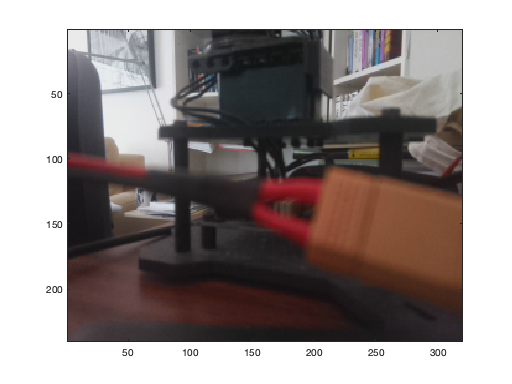

image(img)

function print_json(j1, j2)
    state1 = jsondecode(j1);
    state2 = jsondecode(j2);
    fprintf('Initial\n');
    state1.encoder
    state1.pose
    fprintf('Final\n');
    state2.encoder
    state2.pose
end